#                                                             Henrique Silveira Dutra

#                                                                      202110538

#                                      Laboratório de Sistemas de Comunicação Digital I

#                                                                 Experimento 9

## Atividade Teórica

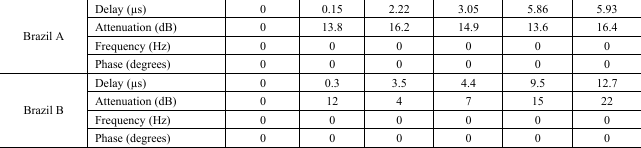

DelayProfileA = [0       0;
               -13.8    0.15e-6;
               -16.2    2.22e-6;
               -14.9    3.05e-6;
               -13.6    5.86e-6;
               -16.4    5.93e-6];


% Cálculo das amplitudes de dB para vezes

AmplitudeA1 = 10^(DelayProfileA(1,1)/20)

AmplitudeA1 = 1

AmplitudeA2 = 10^(DelayProfileA(2,1)/20)

AmplitudeA2 = 0.2042

AmplitudeA3 = 10^(DelayProfileA(3,1)/20)

AmplitudeA3 = 0.1549

AmplitudeA4 = 10^(DelayProfileA(4,1)/20)

AmplitudeA4 = 0.1799

AmplitudeA5 = 10^(DelayProfileA(5,1)/20)

AmplitudeA5 = 0.2089

AmplitudeA6 = 10^(DelayProfileA(6,1)/20)

AmplitudeA6 = 0.1514

SR = 1e6; % Symbol Rate
K = 8; % Fator de Upsample
Fs = K*SR; % Frequêcia de amostragem

% Cálculo dos atrasos de microsegundos para amostras(símbolos)

AtrasoA1 = round(DelayProfileA(1,2)/(1/Fs))

AtrasoA1 = 0

AtrasoA2 = round(DelayProfileA(2,2)/(1/Fs))

AtrasoA2 = 1

AtrasoA3 = round(DelayProfileA(3,2)/(1/Fs))

AtrasoA3 = 18

AtrasoA4 = round(DelayProfileA(4,2)/(1/Fs))

AtrasoA4 = 24

AtrasoA5 = round(DelayProfileA(5,2)/(1/Fs))

AtrasoA5 = 47

AtrasoA6 = round(DelayProfileA(6,2)/(1/Fs))

AtrasoA6 = 47

### Equação de Diferenças - Canal Brasil A


$$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack \;+0\ldotp 2042\cdot x\left\lbrack n-1\right\rbrack \;+\;0\ldotp 1549\cdot x\left\lbrack n-18\right\rbrack \;+\;0\ldotp 1799\cdot x\left\lbrack n-24\right\rbrack \;+\;0\ldotp 2089\cdot x\left\lbrack n-47\right\rbrack \;+\;0\ldotp 1514\cdot x\left\lbrack n-47\right\rbrack$$



$$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack \;+0\ldotp 2042\cdot x\left\lbrack n-1\right\rbrack \;+\;0\ldotp 1549\cdot x\left\lbrack n-18\right\rbrack \;+\;0\ldotp 1799\cdot x\left\lbrack n-24\right\rbrack \;+\;0\ldotp 3603\cdot x\left\lbrack n-47\right\rbrack$$


### Função de Transferência - Canal Brasil A


$$Y\left(Z\right)=X\left(Z\right)\;+\;0\ldotp 2042\cdot Z^{-1} \cdot X\left(Z\right)\;+\;0\ldotp 1549\cdot Z^{-18} \cdot X\left(Z\right)\;+\;0\ldotp 1799\cdot Z^{-24} \cdot X\left(Z\right)\;+\;0\ldotp 3603\cdot Z^{-47} \cdot X\left(Z\right)$$


 
$$Y\left(Z\right)=X\left(Z\right)\cdot \left(1\;+\;0\ldotp 2042\cdot Z^{-1} \;+\;0\ldotp 1549\cdot Z^{-18} \;+\;0\ldotp 1799\cdot Z^{-24} \;+\;0\ldotp 3603\cdot Z^{-47} \right)\;$$



$$H\left(Z\right)=\frac{Y\left(Z\right)}{X\left(Z\right)}=1\;+\;0\ldotp 2042\cdot Z^{-1} \;+\;0\ldotp 1549\cdot Z^{-18} \;+\;0\ldotp 1799\cdot Z^{-24} \;+\;0\ldotp 3603\cdot Z^{-47} \;$$


a = [1];

% Numerador da função de transferência: coeficientes de x[n - atraso]
bA = zeros(1, AtrasoA6+1);  % Tamanho: maior atraso + 1
bA(AtrasoA1+1) = AmplitudeA1;   % x[n]
bA(AtrasoA2+1) = AmplitudeA2;   % x[n-1]
bA(AtrasoA3+1) = AmplitudeA3;   % x[n-18]
bA(AtrasoA4+1) = AmplitudeA4;   % x[n-24]
bA(AtrasoA5+1) = AmplitudeA5 + AmplitudeA6;   % x[n-47]

[impA, nA] = impz(bA, a);  % Calcula a resposta ao impulso


DelayProfileB = [0       0;
               -12.0    0.3e-6;
               -4.0     3.5e-6;
               -7.0     4.4e-6;
               -15.0    9.5e-6;
               -22.0    12.7e-6];

% Cálculo das amplitudes de dB para vezes

AmplitudeB1 = 10^(DelayProfileB(1,1)/20)

AmplitudeB1 = 1

AmplitudeB2 = 10^(DelayProfileB(2,1)/20)

AmplitudeB2 = 0.2512

AmplitudeB3 = 10^(DelayProfileB(3,1)/20)

AmplitudeB3 = 0.6310

AmplitudeB4 = 10^(DelayProfileB(4,1)/20)

AmplitudeB4 = 0.4467

AmplitudeB5 = 10^(DelayProfileB(5,1)/20)

AmplitudeB5 = 0.1778

AmplitudeB6 = 10^(DelayProfileB(6,1)/20)

AmplitudeB6 = 0.0794


% Cálculo dos atrasos de microsegundos para amostras(símbolos)
AtrasoB1 = round(DelayProfileB(1,2)/(1/Fs))

AtrasoB1 = 0

AtrasoB2 = round(DelayProfileB(2,2)/(1/Fs))

AtrasoB2 = 2

AtrasoB3 = round(DelayProfileB(3,2)/(1/Fs))

AtrasoB3 = 28

AtrasoB4 = round(DelayProfileB(4,2)/(1/Fs))

AtrasoB4 = 35

AtrasoB5 = round(DelayProfileB(5,2)/(1/Fs))

AtrasoB5 = 76

AtrasoB6 = round(DelayProfileB(6,2)/(1/Fs))

AtrasoB6 = 102

### Equação de Diferenças - Canal Brasil B


$$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack \;+\;0\ldotp 2512\cdot x\left\lbrack n-2\right\rbrack \;+\;0\ldotp 6310\cdot x\left\lbrack n-28\right\rbrack \;+\;0\ldotp 4467\cdot x\left\lbrack n-35\right\rbrack \;+\;0\ldotp 1778\cdot x\left\lbrack n-76\right\rbrack \;+\;0\ldotp 0794\cdot x\left\lbrack n-102\right\rbrack \;$$


### Função de Transferência - Canal Brasil B


$$Y\left(Z\right)=X\left(Z\right)\;+\;0\ldotp 2512\cdot Z^{-2} \cdot X\left(Z\right)\;+\;0\ldotp 6310\cdot Z^{-28} \cdot X\left(Z\right)\;+\;0\ldotp 4467\cdot Z^{-35} \cdot X\left(Z\right)\;+\;0\ldotp 1778\cdot Z^{-76} \cdot X\left(Z\right)\;+\;0\ldotp 0794\cdot Z^{-102} \cdot X\left(Z\right)$$


 
$$Y\left(Z\right)=X\left(Z\right)\cdot \left(1\;+0\ldotp 2512\cdot Z^{-2} \;+0\ldotp 6310\cdot Z^{-28} \;+\;0\ldotp 4467\cdot Z^{-35} \;+\;0\ldotp 1778\cdot Z^{-76} \;+\;0\ldotp 0794\cdot Z^{-102} \right)\;$$



$$H\left(Z\right)=\frac{Y\left(Z\right)}{X\left(Z\right)}=1\;+0\ldotp 2512\cdot Z^{-2} \;+0\ldotp 6310\cdot Z^{-28} \;+\;0\ldotp 4467\cdot Z^{-35} \;+\;0\ldotp 1778\cdot Z^{-76} \;+\;0\ldotp 0794\cdot Z^{-102} \;$$


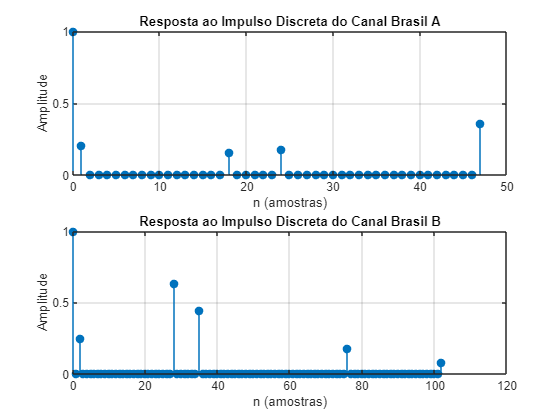

% Numerador da função de transferência: coeficientes de x[n - atraso]
bB = zeros(1, AtrasoB6+1);  % Tamanho: maior atraso + 1
bB(AtrasoB1+1) = AmplitudeB1;   % x[n]
bB(AtrasoB2+1) = AmplitudeB2;   % x[n-2]
bB(AtrasoB3+1) = AmplitudeB3;   % x[n-28]
bB(AtrasoB4+1) = AmplitudeB4;   % x[n-35]
bB(AtrasoB5+1) = AmplitudeB5;   % x[n-76]
bB(AtrasoB6+1) = AmplitudeB6;   % x[n-102]

[impB, nB] = impz(bB, a);  % Calcula a resposta ao impulso

% Plot da resposta ao impulso
figure;
subplot(2,1,1);
stem(nA, impA, 'filled');
xlabel('n (amostras)');
ylabel('Amplitude');
title('Resposta ao Impulso Discreta do Canal Brasil A');
grid on;

subplot(2,1,2);
stem(nB, impB, 'filled');
xlabel('n (amostras)');
ylabel('Amplitude');
title('Resposta ao Impulso Discreta do Canal Brasil B');
grid on;

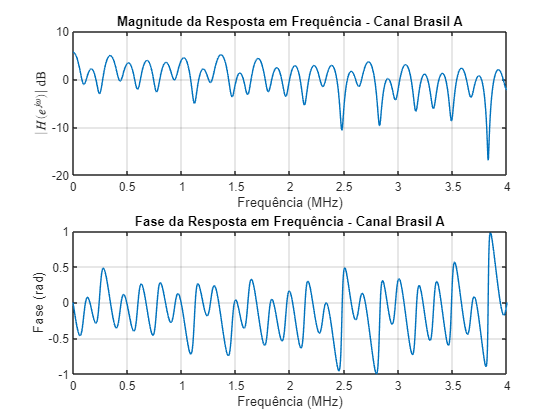

N = 4096;
[HA, fA] = freq_response(bA, a, N,Fs);

figure;
subplot(2,1,1);
plot(fA, 20*log10(abs(HA)));
xlabel('Frequência (MHz)');
ylabel('$|H(e^{j\omega})|$ dB', 'Interpreter','latex');
title('Magnitude da Resposta em Frequência - Canal Brasil A');
grid on;
hold on;

% Plota a fase da resposta em frequência
subplot(2,1,2);
plot(fA, angle(HA));
xlabel('Frequência (MHz)');
ylabel('Fase (rad)');
title('Fase da Resposta em Frequência - Canal Brasil A');
grid on;
hold on;

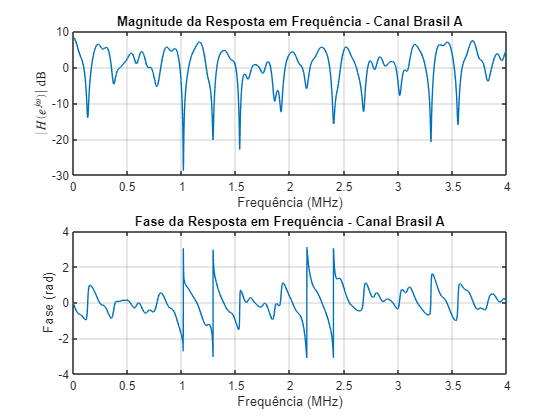

[HB, fB] = freq_response(bB, a, N,Fs);

figure;
subplot(2,1,1);
plot(fB, 20*log10(abs(HB)));
xlabel('Frequência (MHz)');
ylabel('$|H(e^{j\omega})|$ dB', 'Interpreter','latex');
title('Magnitude da Resposta em Frequência - Canal Brasil A');
grid on;
hold on;

% Plota a fase da resposta em frequência
subplot(2,1,2);
plot(fB, angle(HB));
xlabel('Frequência (MHz)');
ylabel('Fase (rad)');
title('Fase da Resposta em Frequência - Canal Brasil A');
grid on;
hold on;

Fc = 2e6;

num_bits = 5e5; % 500.000 bits
bitstream = randi([0, 1], 1, num_bits);


% Chamando a função dos mappers
[I_QPSK, Q_QPSK] = mapper_QPSK(bitstream);

[I_QAM, Q_QAM] = qam16_mapper(bitstream);

% Parâmetros do filtro 
alpha = 0.35;     % Fator de roll-off 
span_rrc = 12;    % Duração do filtro em símbolos

% Criando o filtro RRC
rrc = rcosdesign(alpha, span_rrc, K, 'sqrt');

lpf = rrc;

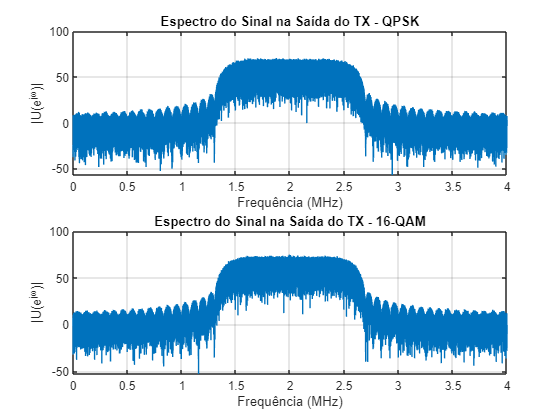

[u_QPSK, U_QPSK, f_MHz_U_QPSK] = modulador(I_QPSK, Q_QPSK, K, lpf, Fc, Fs);
[u_QAM, U_QAM, f_MHz_U_QAM] = modulador(I_QAM, Q_QAM, K, lpf, Fc, Fs);

% Plot do módulo de U(e^(jw))
figure; 
subplot(2,1,1);
plot(f_MHz_U_QPSK, 20*log10(abs(U_QPSK)));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
title('Espectro do Sinal na Saída do TX - QPSK');
grid on;

subplot(2,1,2);
plot(f_MHz_U_QAM, 20*log10(abs(U_QAM)));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
title('Espectro do Sinal na Saída do TX - 16-QAM');
grid on;

% Aplicação dos canais dispersivos nas saídas dos moduladores
QPSKA = filter(bA, 1, u_QPSK);
QPSKB = filter(bB, 1, u_QPSK);

QAM16A = filter(bA, 1, u_QAM);
QAM16B = filter(bB, 1, u_QAM);

% FFTs
fft_QPSKA = fft(QPSKA);
fft_QPSKA = fft_QPSKA(1:length(fft_QPSKA)/2);

fft_QPSKB = fft(QPSKB);
fft_QPSKB = fft_QPSKB(1:length(fft_QPSKB)/2);

fft_QAM16A = fft(QAM16A);
fft_QAM16A = fft_QAM16A(1:length(fft_QAM16A)/2);

fft_QAM16B = fft(QAM16B);
fft_QAM16B = fft_QAM16B(1:length(fft_QAM16B)/2);

% Frequências normalizadas 
omegaQPSKA = linspace(0, pi, length(fft_QPSKA));
omegaQPSKB = linspace(0, pi, length(fft_QPSKB));
omegaQAM16A = linspace(0, pi, length(fft_QAM16A));
omegaQAM16B = linspace(0, pi, length(fft_QAM16B));

% Convertendo para frequências em MHz
f_MHz_QPSKA = omegaQPSKA/pi * (Fs/2)/1e6;
f_MHz_QPSKB = omegaQPSKB/pi * (Fs/2)/1e6;
f_MHz_QAM16A = omegaQAM16A/pi * (Fs/2)/1e6;
f_MHz_QAM16B = omegaQAM16B/pi * (Fs/2)/1e6;

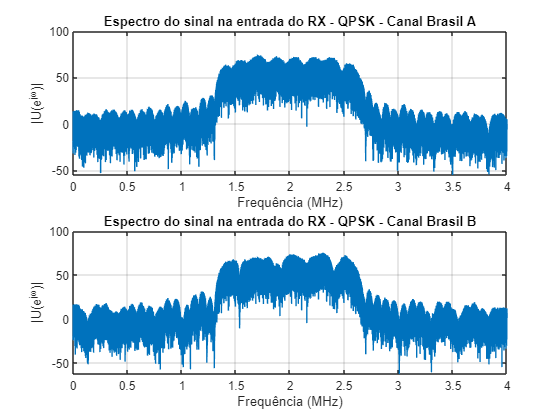

% Plot do módulo de U(e^(jw))
figure; 
subplot(2,1,1);
plot(f_MHz_QPSKA, 20*log10(abs(fft_QPSKA)));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
title('Espectro do sinal na entrada do RX - QPSK - Canal Brasil A');
grid on;

subplot(2,1,2);
plot(f_MHz_QPSKB, 20*log10(abs(fft_QPSKB)));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
title('Espectro do sinal na entrada do RX - QPSK - Canal Brasil B');
grid on;

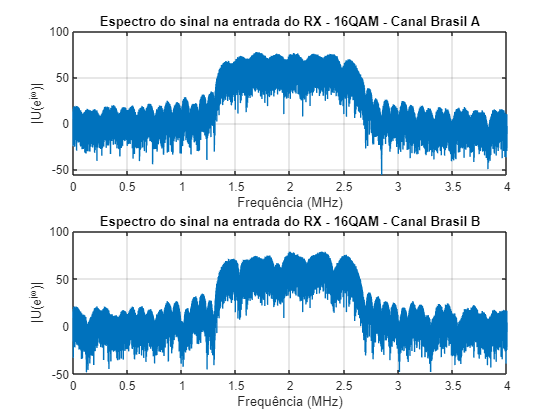

% Plot do módulo de U(e^(jw))
figure; 
subplot(2,1,1);
plot(f_MHz_QAM16A, 20*log10(abs(fft_QAM16A)));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
title('Espectro do sinal na entrada do RX - 16QAM - Canal Brasil A');
grid on;

subplot(2,1,2);
plot(f_MHz_QAM16B, 20*log10(abs(fft_QAM16B)));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
title('Espectro do sinal na entrada do RX - 16QAM - Canal Brasil B');
grid on;

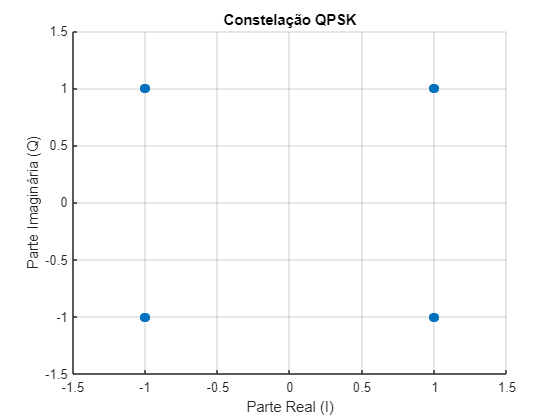

m = 0.5; % Fator de correção 

[I_d,Q_d] = demodulador(u_QPSK, Fc, Fs, rrc, K, m);
[I_dA,Q_dA] = demodulador(QPSKA, Fc, Fs, rrc, K, m);
[I_dB,Q_dB] = demodulador(QPSKB, Fc, Fs, rrc, K, m);

figure;
scatter(I_d, Q_d, 'filled');
xlabel('Parte Real (I)');
ylabel("Parte Imaginária (Q)");
title('Constelação QPSK');
grid on;
axis([-1.5 1.5 -1.5 1.5]);

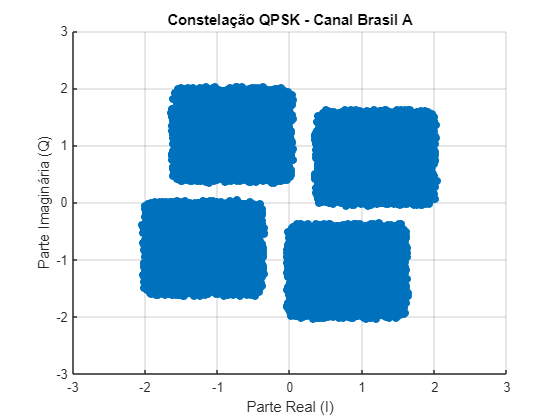


figure;
scatter(I_dA, Q_dA, 'filled');
xlabel('Parte Real (I)');
ylabel("Parte Imaginária (Q)");
title('Constelação QPSK - Canal Brasil A');
grid on;
axis([-3 3 -3 3]);

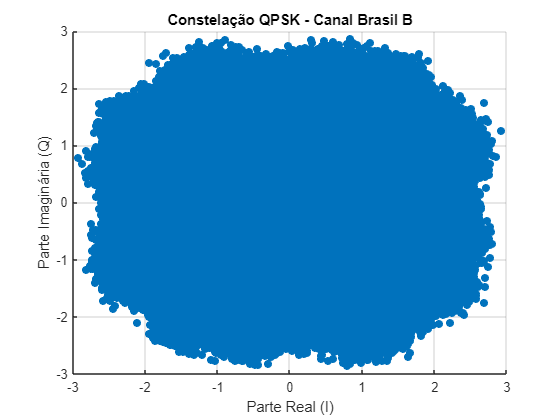


figure;
scatter(I_dB, Q_dB, 'filled');
xlabel('Parte Real (I)');
ylabel("Parte Imaginária (Q)");
title('Constelação QPSK - Canal Brasil B');
grid on;
axis([-3 3 -3 3]);

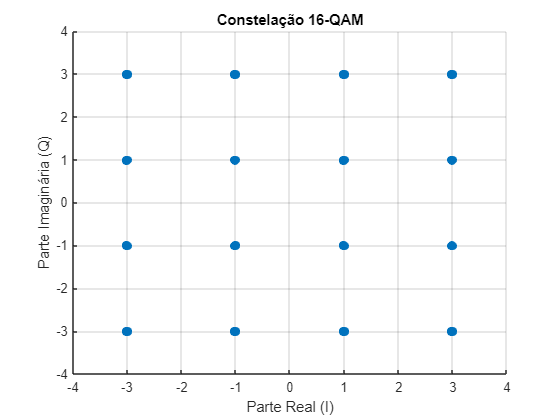

[I_d_QAM,Q_d_QAM] = demodulador(u_QAM, Fc, Fs, rrc, K, m);
[I_dA_QAM,Q_dA_QAM] = demodulador(QAM16A, Fc, Fs, rrc, K, m);
[I_dB_QAM,Q_dB_QAM] = demodulador(QAM16B, Fc, Fs, rrc, K, m);

figure;
scatter(I_d_QAM, Q_d_QAM, 'filled');
xlabel('Parte Real (I)');
ylabel("Parte Imaginária (Q)");
title('Constelação 16-QAM');
grid on;
axis([-4 4 -4 4]);

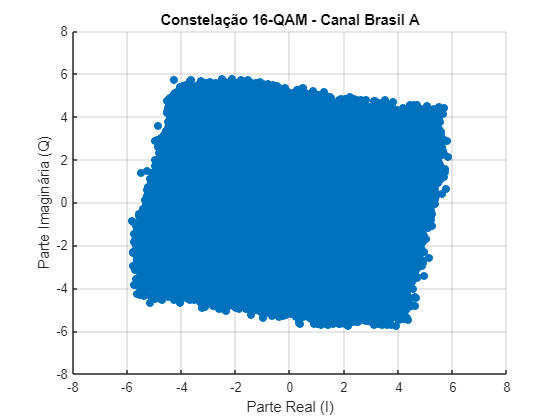


figure;
scatter(I_dA_QAM, Q_dA_QAM, 'filled');
xlabel('Parte Real (I)');
ylabel("Parte Imaginária (Q)");
title('Constelação 16-QAM - Canal Brasil A');
grid on;
axis([-8 8 -8 8]);

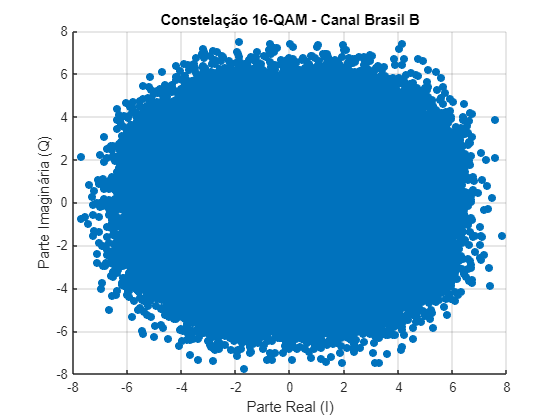


figure;
scatter(I_dB_QAM, Q_dB_QAM, 'filled');
xlabel('Parte Real (I)');
ylabel("Parte Imaginária (Q)");
title('Constelação 16-QAM - Canal Brasil B');
grid on;
axis([-8 8 -8 8]);

SNRs = -20:1:20;
Tsamp = 1/Fs;
Tsym = 1/SR;

EbN0_dB = 10*log10(Tsym/Tsamp) + SNRs - 10*log10(4);
EbN0_dB16 = 10*log10(Tsym/Tsamp) + SNRs - 10*log10(8);

[BER] = curvas_QPSK(K, Fc, Fs, u_QPSK, SNRs, rrc, m, bitstream);

[BER16] = curvas_QAM(K, Fc, Fs, u_QAM, SNRs, rrc, m, bitstream);

[BER_QPSKA] = curvas_QPSK(K, Fc, Fs, QPSKA, SNRs, rrc, m, bitstream);

[BER_QPSKB] = curvas_QPSK(K, Fc, Fs, QPSKB, SNRs, rrc, m, bitstream);

[BER_QAMA] = curvas_QAM(K, Fc, Fs, QAM16A, SNRs, rrc, m, bitstream);

[BER_QAMB] = curvas_QAM(K, Fc, Fs, QAM16B, SNRs, rrc, m, bitstream);

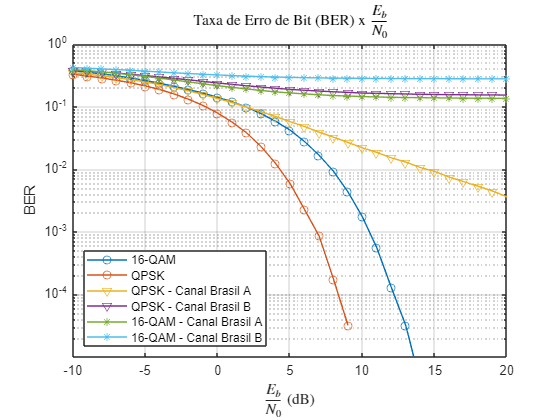

figure;
semilogy(EbN0_dB16, BER16, 'o-', 'DisplayName', '16-QAM');
hold on;
semilogy(EbN0_dB, BER, 'o-', 'DisplayName', 'QPSK');
semilogy(EbN0_dB, BER_QPSKA, 'v-', 'DisplayName', 'QPSK - Canal Brasil A');
semilogy(EbN0_dB, BER_QPSKB, 'v-', 'DisplayName', 'QPSK - Canal Brasil B');
semilogy(EbN0_dB16, BER_QAMA, '*-', 'DisplayName', '16-QAM - Canal Brasil A');
semilogy(EbN0_dB16, BER_QAMB, '*-', 'DisplayName', '16-QAM - Canal Brasil B');
hold off;
xlabel('$\frac{E_b}{N_0}$ (dB)','interpreter','latex');
ylabel('BER');
title('Taxa de Erro de Bit (BER) x $\frac{E_b}{N_0}$','Interpreter','Latex');
legend('Location','southwest');
axis([-10 20 1e-5 1]);
grid on;

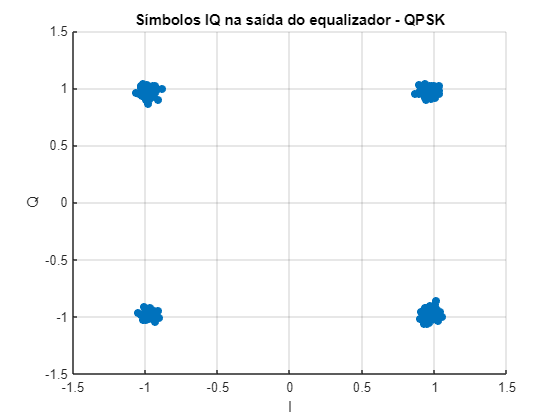

n_treino = 200;

% Chamando a função do mapper QPSK com 400 bits = 200 símbolos
[I_QPSK_LMS, Q_QPSK_LMS] = mapper_QPSK(bitstream(1,1:n_treino*2));

% Aplicando os símbolos no modulador
[u_QPSK_LMS, ~, ~] = modulador(I_QPSK_LMS, Q_QPSK_LMS, K, lpf, Fc, Fs);

% Aplicando o sinal transmitido no demodulador considerando um canal ideal 
[I_d_LMS,Q_d_LMS] = demodulador(u_QPSK_LMS, Fc, Fs, rrc, K, m);

% Aplicando o equalizador LMS
[W, e] = LMS(I_d_LMS, Q_d_LMS, I_QPSK_LMS, Q_QPSK_LMS, 20, 0.01);

% Equalização do canal
IQ_LMS = I_d_LMS + 1i*Q_d_LMS;
out = filter(W, 1, IQ_LMS);

% Plotagem da constelação equalizada
figure;
scatter(real(out), imag(out), 'filled');
xlabel('I');
ylabel('Q');
title('Símbolos IQ na saída do equalizador - QPSK');
grid on;
axis([-1.5 1.5 -1.5 1.5]);

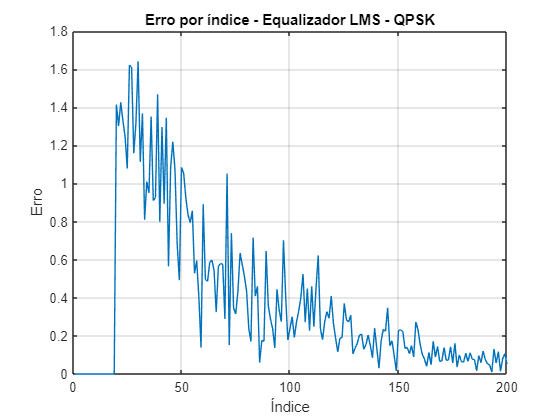

ne = 1:length(e);

figure;
plot(ne, abs(e));
xlabel('Índice');
ylabel('Erro');
title('Erro por índice - Equalizador LMS - QPSK');
grid on;

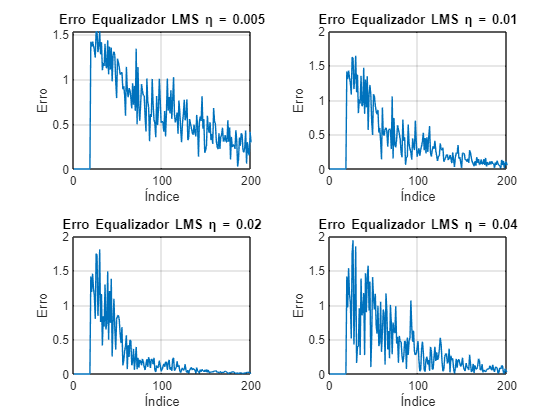

figure;
for eta = [0.005 0.01 0.02 0.04]
    [~, e] = LMS(I_d_LMS, Q_d_LMS, I_QPSK_LMS, Q_QPSK_LMS, 20, eta);

    n = 1:length(e);

    nexttile
    plot(n, abs(e));
    xlabel('Índice');
    ylabel('Erro');
    title(['Erro Equalizador LMS \eta = ', num2str(eta)]);
    grid on;
end

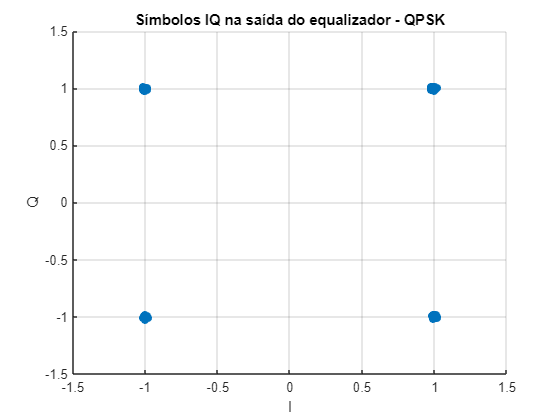

% Aplicando o equalizador LMS
[W1, ~] = LMS(I_d_LMS, Q_d_LMS, I_QPSK_LMS, Q_QPSK_LMS, 20, 0.02);

% Equalização do canal
out1 = filter(W1, 1, IQ_LMS);

% Plotagem da constelação equalizada
figure;
scatter(real(out1), imag(out1),'filled');
xlabel('I');
ylabel('Q');
title('Símbolos IQ na saída do equalizador - QPSK');
grid on;
axis([-1.5 1.5 -1.5 1.5]);

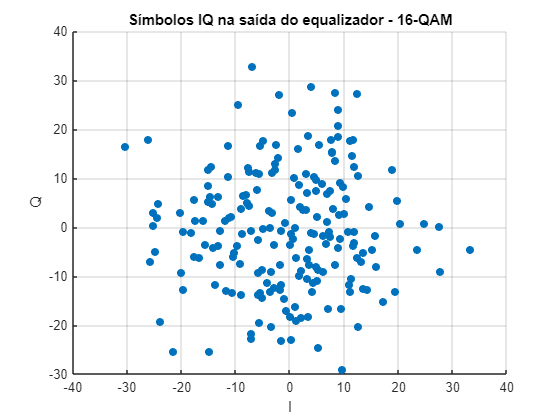

% Chamando a função do mapper QPSK com 800 bits = 200 símbolos
[I_QAM_LMS, Q_QAM_LMS] = qam16_mapper(bitstream(1,1:n_treino*4));

% Aplicando os símbolos no modulador
[u_QAM_LMS, ~, ~] = modulador(I_QAM_LMS, Q_QAM_LMS, K, lpf, Fc, Fs);

% Aplicando o sinal transmitido no demodulador considerando um canal ideal 
[I_d_LMS_QAM,Q_d_LMS_QAM] = demodulador(u_QAM_LMS, Fc, Fs, rrc, K, m);

% Aplicando o equalizador LMS
[W16, e16] = LMS(I_d_LMS_QAM, Q_d_LMS_QAM, I_QAM_LMS, Q_QAM_LMS, 20, 0.01);

% Equalização do canal
IQ_LMS_QAM = I_d_LMS_QAM + 1i*Q_d_LMS_QAM;
out16 = filter(W16, 1, IQ_LMS_QAM);

% Plotagem da constelação equalizada
figure;
scatter(real(out16), imag(out16), 'filled');
xlabel('I');
ylabel('Q');
title('Símbolos IQ na saída do equalizador - 16-QAM');
grid on;

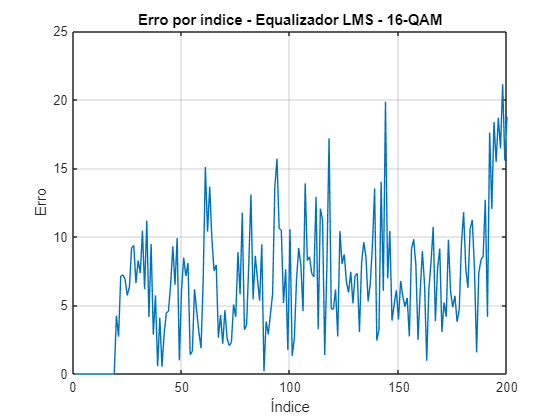

ne16 = 1:length(e16);

figure;
plot(ne16, abs(e16));
xlabel('Índice');
ylabel('Erro');
title('Erro por índice - Equalizador LMS - 16-QAM');
grid on;

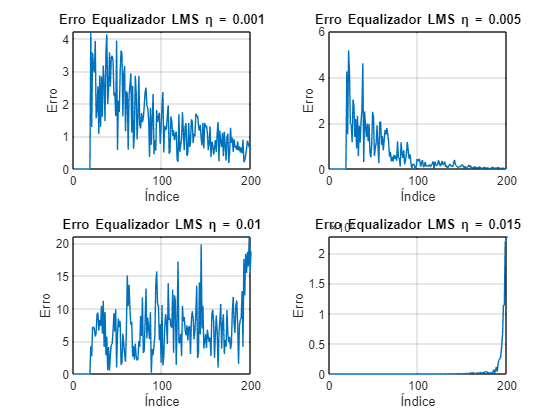

figure;
for eta = [0.001 0.005 0.01 0.015]
    [~, e] = LMS(I_d_LMS_QAM, Q_d_LMS_QAM, I_QAM_LMS, Q_QAM_LMS, 20, eta);

    n = 1:length(e);

    nexttile
    plot(n, abs(e));
    xlabel('Índice');
    ylabel('Erro');
    title(['Erro Equalizador LMS \eta = ', num2str(eta)]);
    grid on;
end

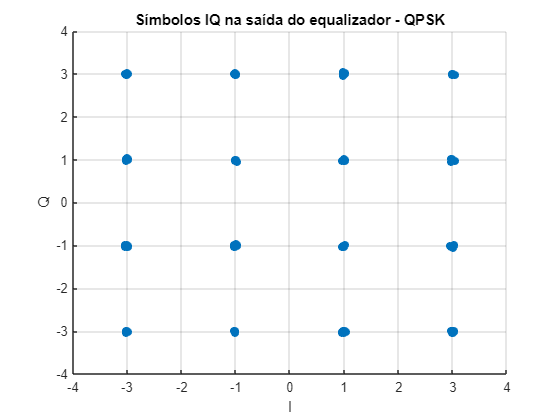

% Aplicando o equalizador LMS
[W_16, ~] = LMS(I_d_LMS_QAM, Q_d_LMS_QAM, I_QAM_LMS, Q_QAM_LMS, 20, 0.005);

% Equalização do canal
out_16 = filter(W_16, 1, IQ_LMS_QAM);

% Plotagem da constelação equalizada
figure;
scatter(real(out_16), imag(out_16),'filled');
xlabel('I');
ylabel('Q');
title('Símbolos IQ na saída do equalizador - QPSK');
grid on;
axis([-4 4 -4 4]);

n_treino_A = 1000;

% Chamando a função do mapper QPSK com 2000 bits = 1000 símbolos
[I_QPSK_LMS_A, Q_QPSK_LMS_A] = mapper_QPSK(bitstream(1,1:n_treino_A*2));

% Aplicando o equalizador LMS
[WA, eA] = LMS(I_dA, Q_dA, I_QPSK_LMS_A, Q_QPSK_LMS_A, 50, 0.005);

% Equalização do canal
IQ_LMS_A = I_dA + 1i*Q_dA;
outA = filter(WA, 1, IQ_LMS_A);

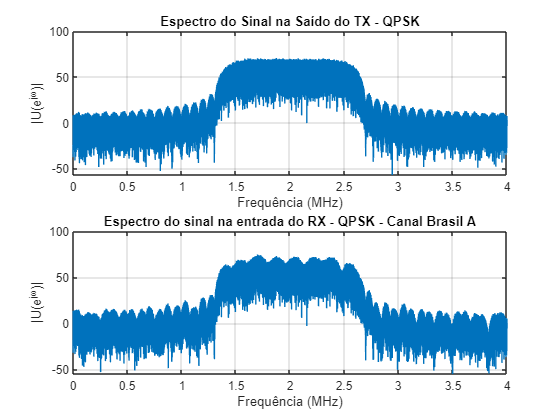

figure; 
subplot(2,1,1);
plot(f_MHz_U_QPSK, 20*log10(abs(U_QPSK)));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
title('Espectro do Sinal na Saído do TX - QPSK');
grid on; 
subplot(2,1,2);
plot(f_MHz_QPSKA, 20*log10(abs(fft_QPSKA)));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
title('Espectro do sinal na entrada do RX - QPSK - Canal Brasil A');
grid on;

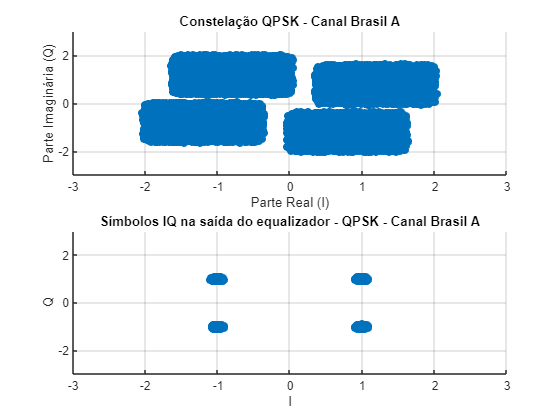

figure;
subplot(2,1,1);
scatter(I_dA, Q_dA, 'filled');
xlabel('Parte Real (I)');
ylabel("Parte Imaginária (Q)");
title('Constelação QPSK - Canal Brasil A');
grid on;
axis([-3 3 -3 3]);

subplot(2,1,2);
scatter(real(outA), imag(outA),'filled');
xlabel('I');
ylabel('Q');
title('Símbolos IQ na saída do equalizador - QPSK - Canal Brasil A');
grid on;
axis([-3 3 -3 3]);

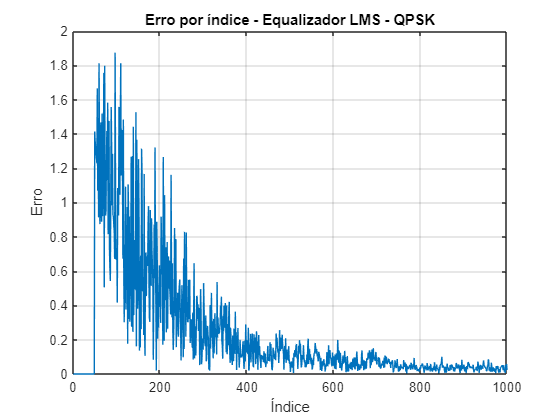

neA = 1:length(eA);

figure;
plot(neA, abs(eA));
xlabel('Índice');
ylabel('Erro');
title('Erro por índice - Equalizador LMS - QPSK');
grid on;

[BER_LMS_A] = BER_QPSK_LMS(SNRs, QPSKA, Fc, Fs, rrc, K, m, I_QPSK_LMS_A, Q_QPSK_LMS_A, 50, 0.005, bitstream);

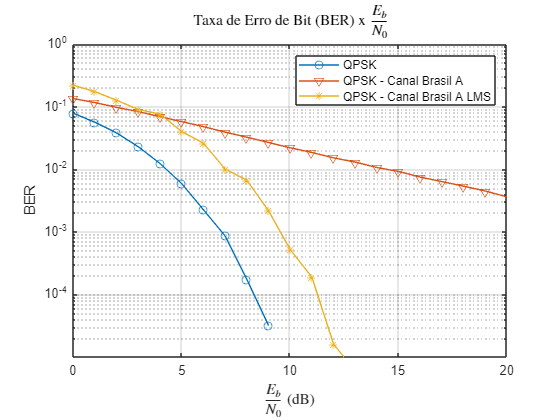

figure;
semilogy(EbN0_dB, BER, 'o-', 'DisplayName', 'QPSK');
hold on;
semilogy(EbN0_dB, BER_QPSKA, 'v-', 'DisplayName', 'QPSK - Canal Brasil A');
semilogy(EbN0_dB, BER_LMS_A, '*-', 'DisplayName', 'QPSK - Canal Brasil A LMS');
hold off;
xlabel('$\frac{E_b}{N_0}$ (dB)','interpreter','latex');
ylabel('BER');
title('Taxa de Erro de Bit (BER) x $\frac{E_b}{N_0}$','Interpreter','Latex');
legend('Location','northeast');
axis([0 20 1e-5 1]);
grid on;

n_treino_B = 2500;

% Chamando a função do mapper QPSK com 200000 bits = 100000 símbolos
[I_QPSK_LMS_B, Q_QPSK_LMS_B] = mapper_QPSK(bitstream(1,1:n_treino_B*2));

% Aplicando o equalizador LMS
[WB, eB] = LMS(I_dB, Q_dB, I_QPSK_LMS_B, Q_QPSK_LMS_B, 110, 5e-4);

% Equalização do canal
IQ_LMS_B = I_dB + 1i*Q_dB;
outB = filter(WB, 1, IQ_LMS_B);

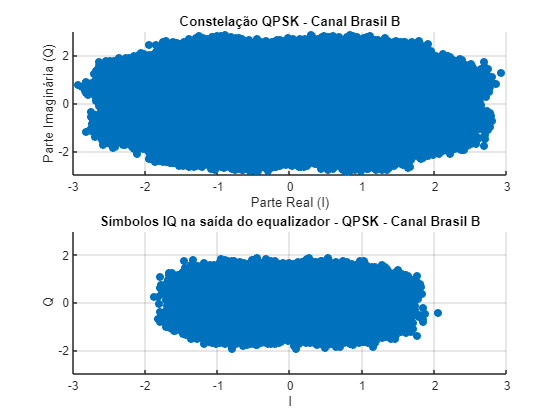

figure;
subplot(2,1,1);
scatter(I_dB, Q_dB, 'filled');
xlabel('Parte Real (I)');
ylabel("Parte Imaginária (Q)");
title('Constelação QPSK - Canal Brasil B');
grid on;
axis([-3 3 -3 3]);

subplot(2,1,2);
scatter(real(outB), imag(outB),'filled');
xlabel('I');
ylabel('Q');
title('Símbolos IQ na saída do equalizador - QPSK - Canal Brasil B');
grid on;
axis([-3 3 -3 3]);

% neB = 1:length(eB);
% 
% figure;
% plot(neB, abs(eB));
% xlabel('Índice');
% ylabel('Erro');
% title('Erro por índice - Equalizador LMS - QPSK');
% grid on;

%[BER_LMS_B] = BER_QPSK_LMS(SNRs, QPSKB, Fc, Fs, rrc, K, m, I_QPSK_LMS_B, Q_QPSK_LMS_B, 50, 0.005, bitstream);

[I_QAM_LMS_A_16, Q_QAM_LMS_A_16] = qam16_mapper(bitstream(1,1:n_treino_A*4));

% Aplicando o equalizador LMS
[WA16, eA16] = LMS(I_dA_QAM, Q_dA_QAM, I_QAM_LMS_A_16, Q_QAM_LMS_A_16, 50, 0.001);

% Equalização do canal
IQ_LMS_A16 = I_dA_QAM + 1i*Q_dA_QAM;
outA16 = filter(WA16, 1, IQ_LMS_A16);

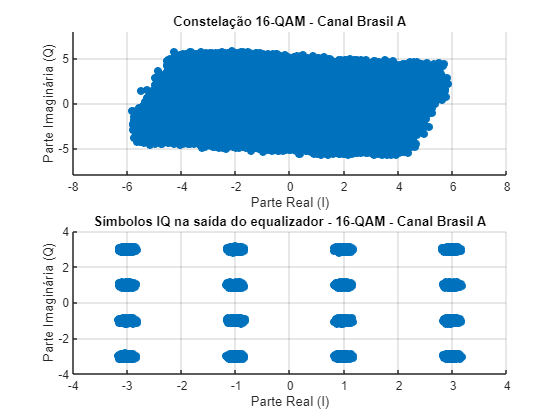

figure;
subplot(2,1,1);
scatter(I_dA_QAM, Q_dA_QAM, 'filled');
xlabel('Parte Real (I)');
ylabel("Parte Imaginária (Q)");
title('Constelação 16-QAM - Canal Brasil A');
grid on;
axis([-8 8 -8 8]);

subplot(2,1,2);
scatter(real(outA16), imag(outA16),'filled');
xlabel('Parte Real (I)');
ylabel("Parte Imaginária (Q)");
title('Símbolos IQ na saída do equalizador - 16-QAM - Canal Brasil A');
grid on;

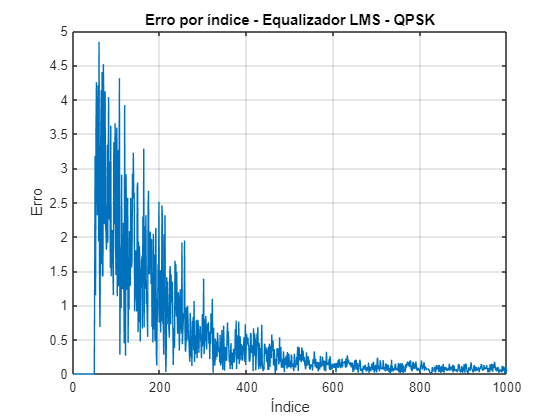

neA16 = 1:length(eA16);

figure;
plot(neA16, abs(eA16));
xlabel('Índice');
ylabel('Erro');
title('Erro por índice - Equalizador LMS - QPSK');
grid on;

[BER_LMS_A_16] = BER_QAM_LMS(SNRs, QAM16A, Fc, Fs, rrc, K, m, I_QAM_LMS_A_16, Q_QAM_LMS_A_16, 25, 0.001, bitstream);

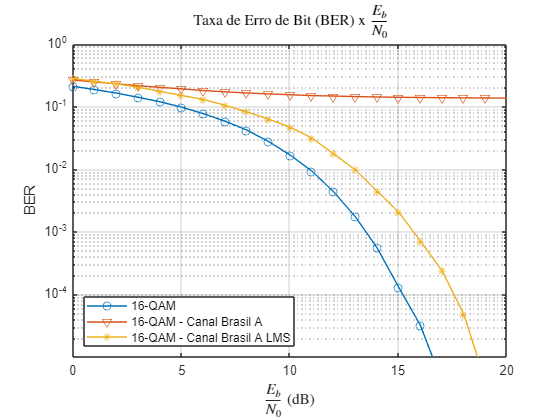

figure;
semilogy(EbN0_dB, BER16, 'o-', 'DisplayName', '16-QAM');
hold on;
semilogy(EbN0_dB, BER_QAMA, 'v-', 'DisplayName', '16-QAM - Canal Brasil A');
semilogy(EbN0_dB, BER_LMS_A_16, '*-', 'DisplayName', '16-QAM - Canal Brasil A LMS');
hold off;
xlabel('$\frac{E_b}{N_0}$ (dB)','interpreter','latex');
ylabel('BER');
title('Taxa de Erro de Bit (BER) x $\frac{E_b}{N_0}$','Interpreter','Latex');
legend('Location','southwest');
axis([0 20 1e-5 1]);
grid on;

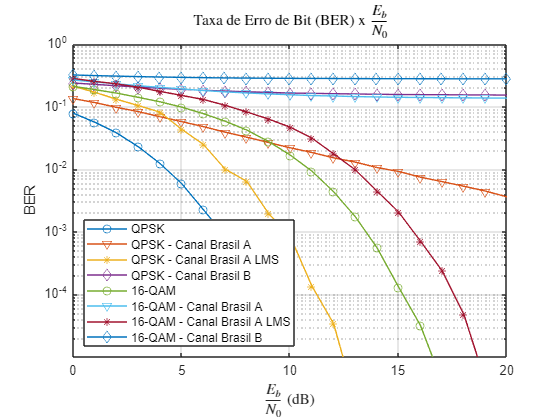

figure;
semilogy(EbN0_dB, BER, 'o-', 'DisplayName', 'QPSK');
hold on;
semilogy(EbN0_dB, BER_QPSKA, 'v-', 'DisplayName', 'QPSK - Canal Brasil A');
semilogy(EbN0_dB, BER_LMS_A, '*-', 'DisplayName', 'QPSK - Canal Brasil A LMS');
semilogy(EbN0_dB, BER_QPSKB, '-diamond', 'DisplayName', 'QPSK - Canal Brasil B');
% semilogy(EbN0_dB, BER_LMS_B, '-cross', 'DisplayName', 'QPSK - Canal Brasil B LMS');
semilogy(EbN0_dB, BER16, 'o-', 'DisplayName', '16-QAM');
semilogy(EbN0_dB, BER_QAMA, 'v-', 'DisplayName', '16-QAM - Canal Brasil A');
semilogy(EbN0_dB, BER_LMS_A_16, '*-', 'DisplayName', '16-QAM - Canal Brasil A LMS');
semilogy(EbN0_dB16, BER_QAMB, '-diamond', 'DisplayName', '16-QAM - Canal Brasil B');
% semilogy(EbN0_dB, BER_LMS_B_16, '*-cross', 'DisplayName', '16-QAM - Canal Brasil B LMS');
hold off;
xlabel('$\frac{E_b}{N_0}$ (dB)','interpreter','latex');
ylabel('BER');
title('Taxa de Erro de Bit (BER) x $\frac{E_b}{N_0}$','Interpreter','Latex');
legend('Location','southwest');
axis([0 20 1e-5 1]);
grid on;